# Project assignment - Group 2

## Part 1

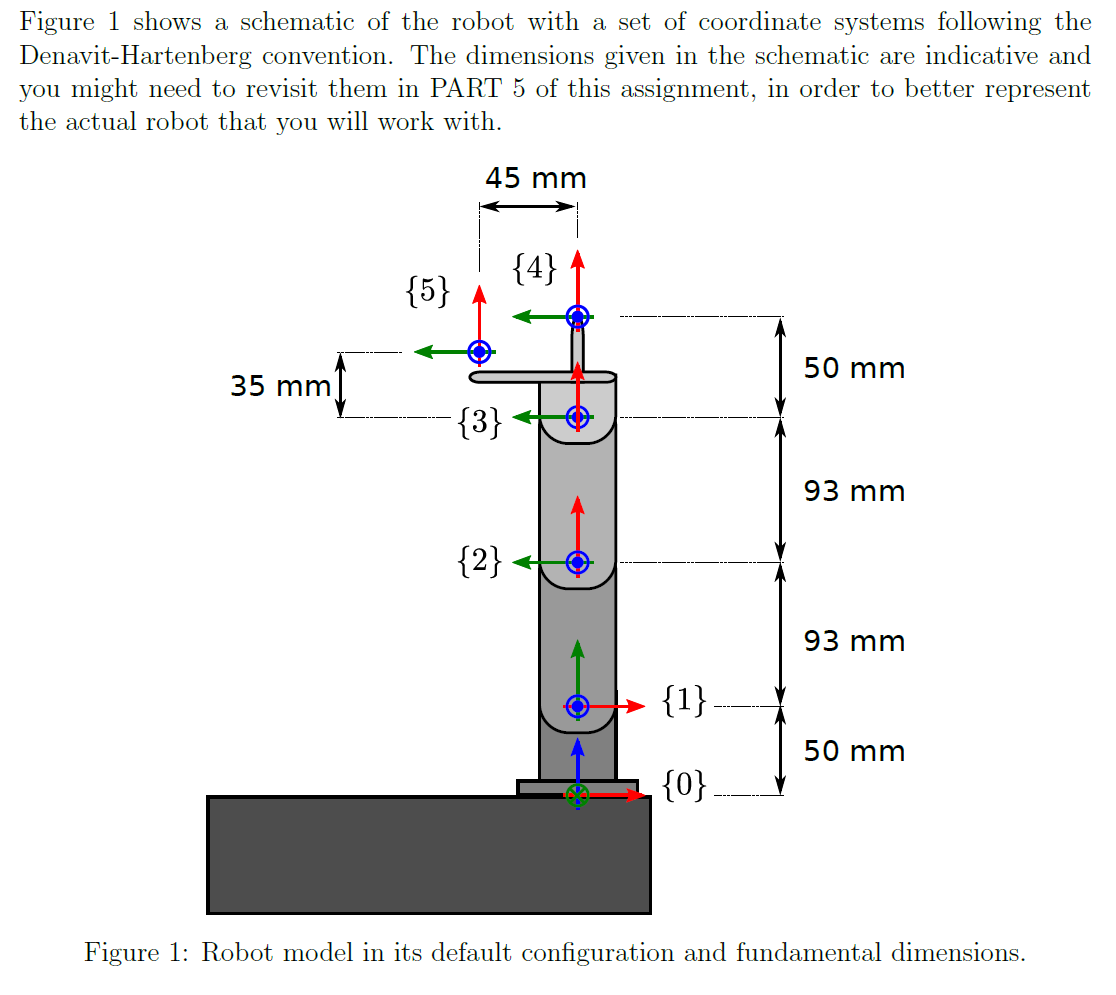

**Problem 1**

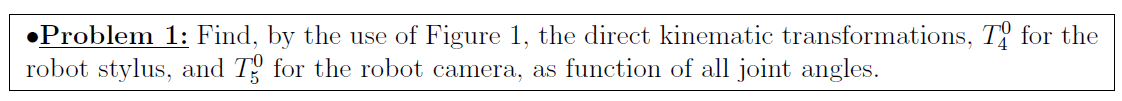

%See matlab function T04 and T05 for description
%Setup
LINK1 = 50;
LINK2 = 93;
LINK3 = LINK2;
LINK4 = 50;
CAMERA_Y = 45;
CAMERA_X = 35;
CAMERA_X_TO_4 = -15;
LINK5 = sqrt(CAMERA_X^2 + CAMERA_Y^2); % from o3 to camera
CAMERA_STYLUS_ANGLE = atan(9/7);

%Forward kinematics
syms q1 q2 q3 q4
T04 = T04(q1,q2,q3,q4); %End effector at non-prescribed joint angles
T05 = T05(q1,q2,q3,q4); %Camera

Function definitions in a script must appear at the end of the file.
Move all statements after the "T05" function definition to before the first local function definition.

**Problem 2**

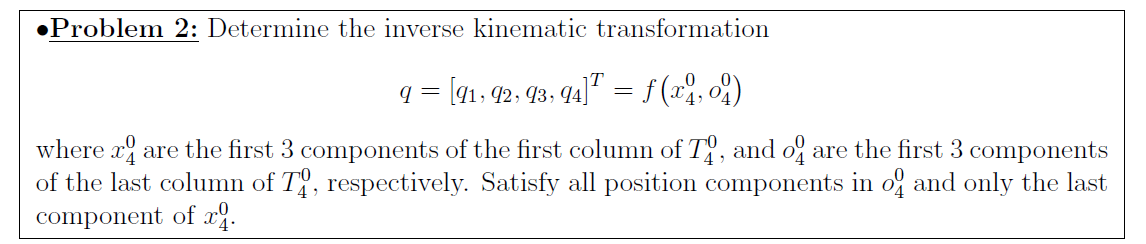

%Kinematic decoupling for o03
x04 = T04(1:3,1); %First three components of T04
o04 = T04(1:3,4); %Last three components of T04
o03 = geto03(o04,x04); %Kinematic decoupling
x03 = o03(1);
y03 = o03(2);
z03 = o03(3);

%Inverse kinematics
q1 = get_q1(o03);
q2 = get_q2(o03);
q3 = get_q3(o03);
q4 = get_q4(o03);
q = get_angles(o03,x04);

**Problem 3**

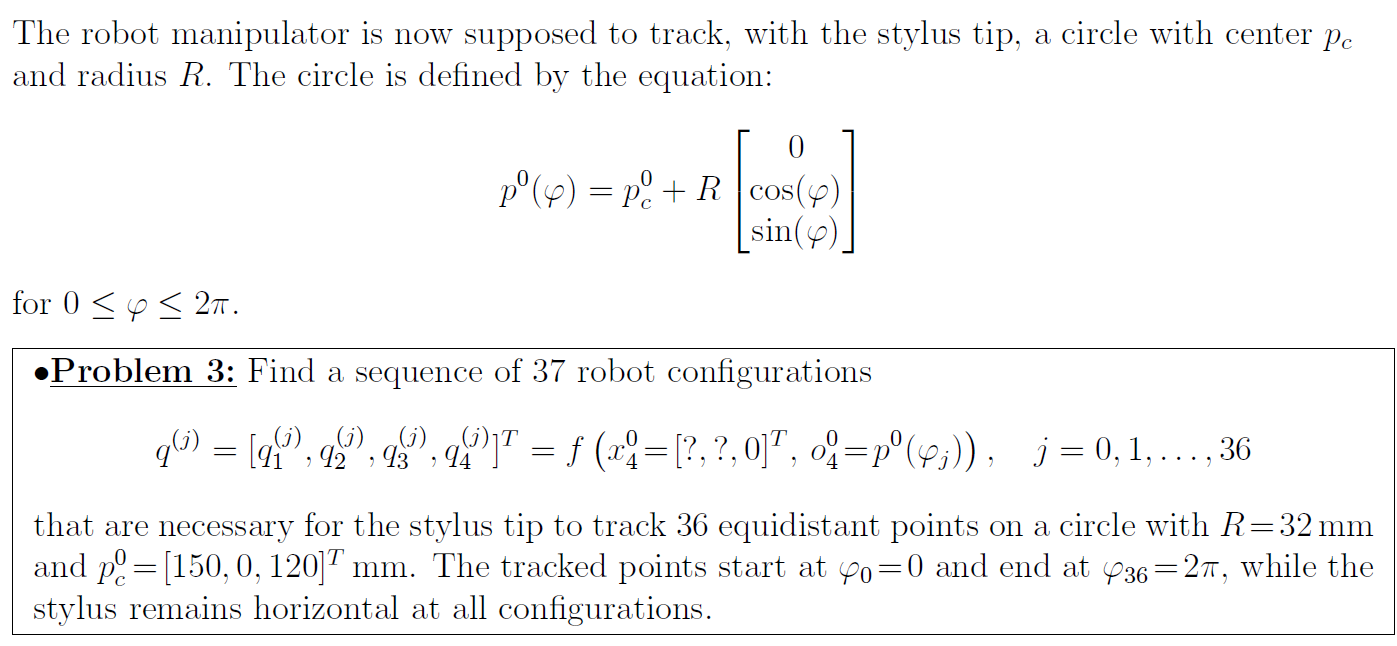

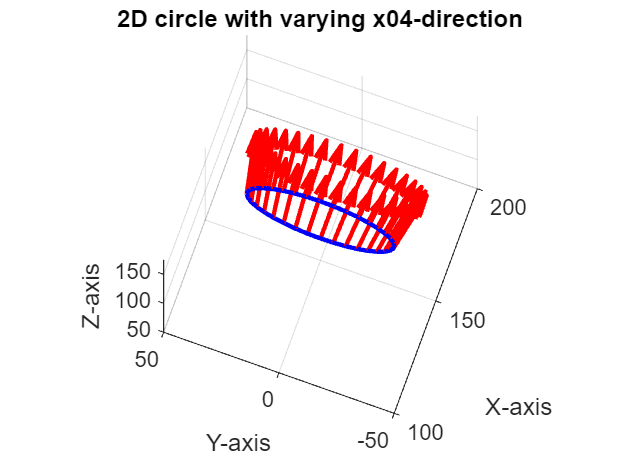

%Finding x04 with relation to all phi angles in circle
syms phi
R = 32; %Radius of circle in mm
x04_straight = [150, 0, 0]; %Direction of x04 axis at phi = pi/2
x04_circle = x04_straight + R*[0, cos(phi), 0]; %Creating vector with varying y-component in relation to phi
x04_circle_unit = x04_circle / (sqrt(x04_circle(1)^2 + x04_circle(2)^2 + x04_circle(3)^2));

%Finding o04 with relation to all phi angles and x04 directions
P_c = [150, 0, 120].'; %Center location of circle
for j = 0:36
    o04 = P_c' + R * [0, cos(((2*sym(pi)) / 36)*j), sin(((2*sym(pi)) / 36)*j)]';
end

%These are used as inputs in inverse kinematic function to get joint angles


% Define parameters
R = 32;                           % Radius of the circle
P_c = [150, 0, 120].';            % Center location of the circle in column vector form
x04_straight = [150, 0, 0];       % Direction of x04 axis at phi = pi/2

% Define the number of segments for the circle (360/10 = 36 segments in total)
num_points = 36;                 
theta = linspace(0, 2*pi, num_points + 1);  % Generate theta values from 0 to 2*pi

% Calculate the circle points in 3D space
circle_points = zeros(3, num_points + 1); % Initialize an empty matrix to store the points
unit_vectors = zeros(3, num_points + 1);   % Initialize a matrix to store unit vectors

for j = 1:(num_points + 1)
    % Calculate the current point on the circle
    circle_points(:, j) = P_c + R * [0; cos(theta(j)); sin(theta(j))];
    
    % Calculate phi for each point (same as theta in this context)
    phi = theta(j);
    
    % Calculate x04_circle for each point
    x04_circle = x04_straight + R * [0, cos(phi), 0];
    
    % Calculate the unit vector for the current point
    x04_circle_unit = x04_circle / norm(x04_circle);
    
    % Store the unit vector
    unit_vectors(:, j) = x04_circle_unit;
end

% Plot the circle in 3D space
figure;
plot3(circle_points(1, :), circle_points(2, :), circle_points(3, :), 'b', 'LineWidth', 2);
grid on;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('2D circle with varying x04-direction');
axis equal;
hold on;

% Set axis limits to make the plot appear larger
xlim([100, 200]);
ylim([-50, 50]);
zlim([50, 175]);

% Plot the directional vectors at each point on the circle
for j = 1:(num_points + 1)
    % Extract the point on the circle
    point = circle_points(:, j);
    
    % Extract the unit vector
    dir_vector = unit_vectors(:, j);
    
    % Plot an arrow representing the vector using quiver3 with larger scale factor
    quiver3(point(1), point(2), point(3), dir_vector(1), dir_vector(2), dir_vector(3), ...
            25, 'r', 'LineWidth', 2, 'MaxHeadSize', 3);  % 2.0 is the increased scale factor for larger arrows
end

% Set view to 3D and show grid
view(3);
hold off;

**Problem 4**

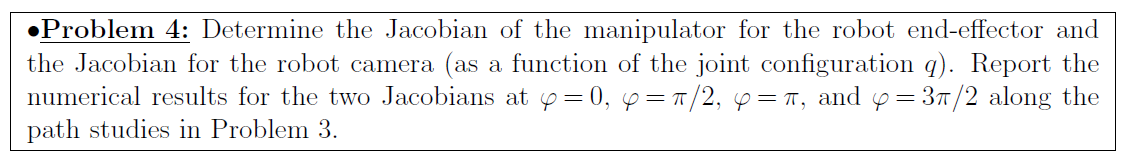

%Jacobi for end-effector
phi_1 = 0;
phi_2 = pi/2;
phi_3 = (3*pi)/2;
T02 = T01*T12;
T03 = T01*T12*T23;

% z-axis of coordinate frames
z0 = [0;0;1];
z1 = [T01(1,3);T01(2,3);T01(3,3)];
z2 = [T02(1,3);T02(2,3);T02(3,3)];
z3 = [T03(1,3);T03(2,3);T03(3,3)];
z4 = [T04(1,3);T04(2,3);T04(3,3)];

% Points of origin for coordinate frames
o0 = [0;0;0];
o1 = [T01(1,4);T01(2,4);T01(3,4)];
o2 = [T02(1,4);T02(2,4);T02(3,4)];
o3 = [T03(1,4);T03(2,4);T03(3,4)];
o4 = [T04(1,4);T04(2,4);T04(3,4)];

J1 = [cross(z0,(o4-o0));z0];
J2 = [cross(z1,(o4-o1));z1];
J3 = [cross(z2,(o4-o2));z2];
J4 = [cross(z3,(o4-o3));z3];
J_end_eff = [J1, J2, J3, J4];

%Evaluate numerically at different angles in circle
%OBSOBS Make a function for this so it's less hard coded. 

%o04_0 = P_c + R * [0, cos(0), sin(0)]; %For phi = 0
%x04_circle_0 = x04_straight + R*[0, cos(0), 0]; %For phi = 0
%x04_circle_unit = x04_circle_0 / (sqrt(x04_circle_0(1)^2 + x04_circle_0(2)^2 + x04_circle_0(3)^2))


%o04_pi_2 =  P_c + R * [0, cos(pi/2), sin(pi/2)]; %For phi = pi/2
%x04_circle_1 = x04_straight + R*[0, cos(pi/2), 0]; %For phi = pi/2
%x04_circle_unit_1 = x04_circle_1 / (sqrt(x04_circle_1(1)^2 + x04_circle_1(2)^2 + x04_circle_1(3)^2))


%o04_pi = P_c + R * [0, cos(pi), sin(pi)]; %For phi = pi
%x04_circle_2 = x04_straight + R*[0, cos(pi), 0]; %For phi = pi
%x04_circle_unit_2 = x04_circle_2 / (sqrt(x04_circle_2(1)^2 + x04_circle_2(2)^2 + x04_circle_2(3)^2))


%o04_3 = P_c + R * [0, cos((3*pi)/2), sin((3*pi)/2)]; %For phi = 3*pi/2
%x04_circle_3 = x04_straight + R*[0, cos((3*pi)/2), 0]; %For phi = 3*pi/2
%x04_circle_unit_3 = x04_circle_3 / (sqrt(x04_circle_3(1)^2 + x04_circle_3(2)^2 + x04_circle_3(3)^2))

%--------------------------------------------------
%Jacobi for robot camera

z5 = [T05(1,3);T05(2,3);T05(3,3)];
o5 = [T05(1,4);T05(2,4);T05(3,4)];
J5 = [cross(z3,(o5-o3));z3];
J_cam = [J1, J2, J3, J5];

%Evaluate numerically at different angles in circle

%Same procedure as above only with camera end-effector coordinate frame

**Problem 5**

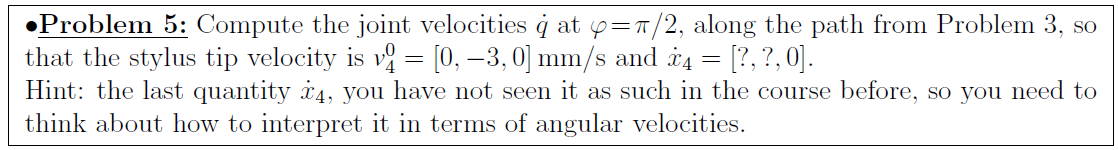

%x_dot4 is a representation of how fast the robot end effector is moving in
%relation to the end-effector x-axis.
syms wx wy wz q_dot_1 q_dot_2 q_dot_3 q_dot_4 %angular velocity coordinates

V04 = [0, -3, 0].'; %Joint velocities at pi/2
omega_n = q_dot_1 * z0 + T01(1:3,1:3)*q_dot_2*z1 + T02(1:3,1:3)*q_dot_3*z2 + T03(1:3,1:3)*q_dot_4*z3;
skew_matrix = [0, -omega_n(3), omega_n(2); omega_n(3), 0 , -omega_n(1); -omega_n(2), omega_n(1), 0]

R_dot = skew_matrix * R04

x_dot = R_dot(:,1)


J_plus = J_end_eff.' * (J_end_eff * J_end_eff.')^-1 ;


## Part 2

## Part 3